clearvars;
clc;
root = 'C:/Users/kelle/Documents/Research/M4';
cd(root);

% Global constants
global kb q0 me T0 ne_0 CO2 O T_Ke T_Ki T_Je T_Ji T_Ee T_Ei O2p_0 CO2p_0 Op_0 alt v1 k2 v3 k4 k5 k6 k7 k8 k9 k10
global R1 R2 R3 R4 R5 R6 R7 R8 R9 R10 s1 s2 s3 temp

R1 = 1;
R2 = 1;
R3 = 1;
R4 = 1;
R5 = 1;
R6 = 1;
R7 = 1;
R8 = 1;
R9 = 1;
R10= 1;

s1 = 1; % CO2p
s2 = 1; % O2p
s3 = 1; % Op

temp = 0;

kb = 1.3806e-23;
q0 = 1.602e-19;
me = 9.109e-31;
T0 = 2.5e-4;

n = 301; % number of lines in Profiles.in

fName1 = 'input/Profiles.in';
fid1 = fopen(fName1,'r');
if fid1 == -1
    disp("File "+fName1+" doesn't currently exist in "+pwd);
    return;
end
for i=1:n
    line1(i,:) = textscan(fid1,'%f %f %f %f %f %f %f %f %f %f %f %f %f %f %f %f %f %f',1, 'headerlines',1);
end

fName2 = 'input/Partition.in';
fid2 = fopen(fName2,'r');
if fid2 == -1
    disp("File "+fName2+" doesn't currently exist in "+pwd);
    return;
end
for i=1:n
    line2(i,:) = textscan(fid2,'%f %f %f %f',1, 'headerlines',1);
end

% Convert to matrices
line1 = cell2mat(line1);
line2 = cell2mat(line2);

% Remove unrelated data
line1(:,12:18) = [];
line1(:,8)     = [];
line1(:,2:5)   = [];
line2(:,1)     = [];

% Updates units
line1(:,1) = line1(:,1)./1e3; % m -> km
line1(:,2) = line1(:,2)./1e6; % m-3 -> cm-3
line1(:,3) = line1(:,3)./1e6; % m-3 -> cm-3
line1(:,4) = line1(:,4)./1e6; % m-3 -> cm-3

fclose(fid1);
fclose(fid2);



% Replaces 100-240 km with profile obtained from Fox 1979 Fig 2.
tempflag = 1;
if (tempflag)
    global newOx
    global newCO2x
    
    CO2 = [1035234.6223040696, 240.09933118050822,1169270.6823145165, 239.22971464476944,1311490.9538072124, 237.6959662610882,1471035.2175617446, 236.25905474682466,1649996.3860220665, 234.8498109095376,1850729.3648607756, 233.44056707225053,2075893.1252924623, 232.05899091193996,2328427.7229169705, 230.62207939767643,2637096.960042297, 229.7179213059198,2952336.878053209, 228.47216331142187,3234401.8215732495, 227.57273985716452,3349396.060498542, 226.33931381328125,3757039.8028902817, 225.17907906878258,4213795.342511444, 223.35482007684817,4726220.651327616, 221.69656714677274,5052877.0181559725, 220.1002744142965,5561017.531457194, 219.76930756972394,6543865.238886187, 218.35390001674023,7340042.489947561, 216.99999153340613,8233129.619093693, 215.67375072704854,9234927.359469643, 214.37517759766746,10358571.36761224, 213.04893679130984,11618875.266809335, 211.69502830797578,13032582.063486978, 210.3687875016182,14618299.219263809, 209.0425466952606,16396793.301553737, 207.66097053495002,18392027.382751316, 206.3900650825454,20629845.890877575, 205.0638242761878,23139947.14255883, 203.7375834698302,25955589.28987464, 202.4390103404491,29114124.064861238, 201.195772565021,32656535.367561545, 199.8695317586634,36630326.53153375, 198.59862630625878,41087258.92757024, 197.2723854999012,46086937.69448556, 196.00148004749659,51694487.09669602, 194.675239241139,57984612.815506764, 193.3766661117579,65040436.082095236, 192.10576065935328,72954481.51981081, 190.80718752997217,82625218.68265602, 189.86844484199491,91797758.59582125, 188.76339481073975,101439480.25982389, 186.71756159462421,113301733.8149634, 186.1106119166056,127088788.18644038, 184.839706464201,142554218.48412055, 183.59646868877286,159900844.126529, 182.32556323636823,179359172.39189363, 181.08232546094013,201186380.87344104, 179.86675536248848,225666508.24639195, 178.5681822331074,251677796.78085217, 177.36912235641597,282587032.7120763, 176.35830813166126,318495154.76558983, 175.05981032263492,357254589.5395286, 173.8442402241833,400726902.66833866, 172.57333477177866,449495800.4287344, 171.38543235030352,504199925.82902044, 170.19752992882837,565570009.9487213, 169.0926305382827,634409923.0626805, 167.987731147737,711621823.5296658, 166.82749640323837,798230925.0129011, 165.66726165873973,895349872.3610775, 164.31335317540564,1063718656.7849708, 162.76667479749307,1193180280.9916933, 161.6064400529944,1338398244.560649, 160.44620530849576,1501305077.0424209, 159.34130591795008,1684032219.0815687, 158.2087388504279,1888990123.0424685, 157.04850410592925,2118924263.7087603, 155.97127239236005,2376823194.995707, 154.83870532483792,2666190839.9431953, 153.87214431917468,2990713609.075817, 152.767244928629,3354786432.2128, 151.74534856901278,3763123512.4097457, 150.64044917846712,4221183382.8623343, 149.56321746489792,4735023282.295207, 148.51365342830522,5311438653.119476, 147.49175706868903,5957994098.789766, 146.44219303209633,6683254010.731241, 145.3926289955036,7496836143.117525, 144.3707326358874,8409625917.861136, 143.45950698417715,9432665818.838917, 142.0225954699136,10994586638.390238, 140.97363399615887,12333067512.818968, 139.97940531351912,13834357932.04456, 138.92984127692642,15518475640.046564, 137.9079449173102,17407435945.989185, 136.83071320374103,19526617035.08933, 135.8364845211013,21903787210.13722, 134.8422558384616,24570354060.040794, 133.84802715582185,27561548733.287926, 132.85379847318217,30916891418.053123, 131.85956979054242,34680713489.849785, 130.8653411079027,38902743225.43091, 129.871112425263,43638762821.49596, 128.87688374262325,48951102836.40546, 127.85498738300706,54911498013.49911, 126.97142940827328,61597033714.14262, 126.03253607958658,69096198405.54297, 125.06597507392331,77509505233.54796, 124.18241709918956,86946373341.76657, 123.2435237705028,97532190594.01094, 122.3046304418161,109407384953.73947, 121.39340479010582,122727247108.64531, 120.42684378444258,137668743195.30844, 119.46028277877934,154431595622.15103, 118.5767248040456,173233813430.62274, 117.63783147535884,194328110856.36264, 116.78194117760157,217987773582.18256, 115.84304784891484,244532873225.13928, 115.01482522813404,274307739852.41385, 114.13126725340027,307708060476.85205, 113.24770927866652,345171857643.489, 112.30881594997976,387204588216.0451, 111.480593329199,434347175681.6985, 110.54170000051224,487241497097.0952, 109.74114505670795,546571814050.7509, 108.88525475895068,613129690337.053, 108.05703213816989,687789133504.6034, 107.20114184041262,771558807408.8433, 106.48358992753779,865505524194.6318, 105.60003195280402,970891402208.4154, 104.71647397807024,1089136283201.1941, 103.97125438821894,1221764047993.8728, 103.14303176743815,1370535547634.0347, 102.2871414696808,1552147855751.0452, 101.11875706279875];
    O = [12834030.91353184, 249.52183673299504,13853640.600077199, 247.41180812422482,14811518.217684507, 245.17766018552695,15685077.66872108, 243.2469150533189,16610240.224571254, 241.3713340677454,17590059.02420972, 239.55091722880638,18627400.39630431, 237.56500794996384,19726209.13416311, 235.74459111102482,20889732.22568029, 233.8690101254513,22121884.113297433, 231.99342913987778,23426828.391319867, 230.17301230093878,24808627.378085416, 228.29743131536526,26272318.850430816, 226.58734276969528,28089099.56795167, 224.4497320876078,30031736.44669576, 222.3948676254721,31803430.69837017, 220.62961493316763,33679145.73673651, 218.69886980095959,35666191.519619614, 216.9887812552896,37769912.3682281, 215.1132002697161,39998113.08342187, 213.34794757741162,42764058.52588081, 211.21033689532413,45721387.171879865, 209.1003082865539,48883771.34123671, 207.11439900771137,52766404.43605075, 204.79750484906174,56416067.15155727, 202.81159557021917,60317494.12628953, 200.70156696144898,65108018.90541905, 198.34329969282345,70279536.13294406, 196.06777864414966,75861545.15948094, 193.75088448550002,82673182.01608954, 191.17196063033646,85185733.14309004, 189.28849905238656,95423719.82557377, 188.2482608587071,101192538.78519043, 186.59333645967166,109235152.08191825, 184.8202031749908,115507291.6848279, 181.71130948251704,124682936.33982445, 179.5185346537951,134587473.9816329, 177.32575982507308,145278806.2625299, 175.1329849963511,156820595.36316553, 173.0229563875809,169277451.21414044, 170.788808448883,182725155.1859947, 168.63740673013692,197244089.25184137, 166.65149745129438,212915089.26785156, 164.58284195250005,229831146.82872045, 162.51418645370572,248089344.85743833, 160.36278473495963,267803954.48978877, 158.45962167606885,289081990.5057014, 156.4323392872504,311058102.2833311, 154.48780311838374,330470384.73695207, 152.99837115925183,340036086.940452, 150.7182530983585,368494216.0451328, 149.6554238732002,385788187.94945467, 148.3314843539718,427774750.19427896, 146.64346146695567,475225950.3044047, 144.6134208708055,503965076.94427955, 143.1681202289812,559111277.7361438, 141.32196012161273,609317599.4145317, 138.80739443752276,657747227.3334936, 137.06972381853552,710020870.3868412, 135.24930697959653,773817831.3124073, 133.30477081072985,843353335.0340674, 131.44298086181496,910381162.5145476, 129.66393713285183,996940983.8341322, 127.67802785400929,1050652801.693246, 125.30596954872513,1167311230.6395555, 124.36817905593836,1309322385.6030076, 122.7132546569029,1427029315.6445472, 121.24956596620044,1627136011.910285, 119.56889829873552,1799022319.9247055, 119.27101190690917,1970459558.3233147, 117.93761567682915,2216457997.6206145, 117.39910853111127,2481574416.9858127, 116.77207606436562,2897792636.3909235, 115.28678141623129,3219453471.3232813, 114.02490156196674,3611379775.229853, 113.16985728913176,4332014021.471711, 112.39755923624853,5048981575.412227, 111.06672419869085,5609470254.169429, 109.88759056437809,6601090590.241252, 109.06012836486036,7693761768.274221, 107.96374095049936,8773109442.684088, 106.89690575754972,10253500349.196684, 105.97783167165682,12181899279.791996, 104.85845919619811,14198227039.622887, 103.66093751300718,16190111798.705692, 102.6177440971866,20040182712.644714, 100.9551361205842];
    
    highO = [85900, 88811, 91822, 94934, 98152, 101478, 104918, 108474, 112151, 115952, 119883, 123946, 128147, 132491, 136982, 141625, 146425, 151388, 156519, 161825, 167310, 172981, 178844, 184906, 191173, 197653, 204353, 211279, 218440, 225845, 233500, 241414, 249597, 258057, 266804, 275847, 285197, 294864, 304858, 315191, 325875, 336920, 348340, 360147, 372355, 384976, 398024, 411516, 425464, 439885, 454795, 470210, 486148, 502626, 519663, 537277, 555488, 574316, 593783, 613909, 634718, 656231, 678474, 701471, 725248, 749830, 775246, 801523, 828691, 856779, 885820, 915845, 946887, 978982, 1012165, 1046472, 1081943, 1118615, 1156531, 1195732, 1236261, 1278164, 1321488, 1366280, 1412590, 1460470, 1509973, 1561153, 1614069, 1668778, 1725341, 1783822, 1844285, 1906797, 1971428, 2038250, 2107337, 2178765, 2252615, 2328967, 2407908, 2489524, 2573907, 2661150, 2751350, 2844607, 2941025, 3040712, 3143777, 3250336, 3360506, 3474411, 3592176, 3713934, 3839818, 3969969, 4104531, 4243655, 4387494, 4536209, 4689964, 4848931, 5013286, 5183212, 5358897, 5540538, 5728335, 5922497, 6123241, 6330789, 6545372, 6767228, 6996604, 7233755, 7478944, 7732443, 7994535, 8265511, 8545671, 8835328, 9134802, 9444428, 9764548, 10095518, 10437707, 10791494, 11157273, 11535450, 11926445, 12330694, 12748644, 13180761, 13627524, 14089430, 14566993, 15060743, 15571229, 16099017, 16644695, 17208869, 17792166];
    highCO2 = [2, 2, 2, 2, 3, 3, 3, 3, 4, 4, 4, 5, 5, 6, 6, 7, 7, 8, 8, 9, 10, 11, 12, 13, 14, 15, 16, 18, 19, 21, 23, 25, 27, 29, 32, 35, 38, 41, 45, 49, 53, 57, 62, 68, 74, 80, 87, 95, 103, 112, 121, 132, 143, 156, 169, 184, 200, 218, 237, 257, 279, 304, 330, 359, 390, 424, 461, 501, 544, 592, 643, 699, 760, 826, 897, 975, 1060, 1152, 1252, 1361, 1479, 1608, 1748, 1900, 2065, 2244, 2439, 2651, 2881, 3132, 3404, 3700, 4021, 4371, 4751, 5163, 5612, 6100, 6630, 7206, 7832, 8513, 9253, 10057, 10931, 11881, 12913, 14036, 15255, 16581, 18022, 19588, 21291, 23141, 25152, 27338, 29713, 32296, 35102, 38153, 41468, 45072, 48989, 53247, 57874, 62903, 68370, 74312, 80770, 87789, 95418, 103710, 112723, 122519, 133167, 144739, 157318, 170989, 185849, 202000, 219554, 238635, 259373, 281913, 306413, 333041, 361984, 393442, 427634, 464797, 505189, 549092, 596811, 648676, 705049, 766320, 832917, 905300, 983975, 1069486, 1162429];

    i = 1;
    while i <= length(CO2)-1
        CO2x(ceil(i/2)) = CO2(i);
        CO2y(ceil(i/2)) = CO2(i+1);
        i = i+2;
    end
    i = 1;
    while i <= length(O)-1
        Ox(ceil(i/2)) = O(i);
        Oy(ceil(i/2)) = O(i+1);
        i = i+2;
    end
    for i = 1:n
        alt = (n+99)-i+1;
        if (alt > 240)
            newOx(i)   = highO(i);
            newCO2x(i) = highCO2(i);
        else
            newOx(i)   = interp1(Oy,Ox,alt);
            newCO2x(i) = interp1(CO2y,CO2x,alt);
        end
        newOy(i) = alt;
    end
    
    newCO2y = newOy;
    newOx(n) = 2.1e10;
    newCO2x(n) = 1.9e12;
    newCO2x(n-1) = 1.6e12;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


badi       = [];
numsolved  = 0;
numskipped = 0;
fulldata   = zeros(n,4);
x0         = zeros(n,4);
skip       = 1;           % set to 1 to not skip any

for i=1:n
    alt  = line1(i,1);
    O    = line1(i,2);
    CO2  = line1(i,3);
    ne_0 = line1(i,4);
    T_Ke = line1(i,5);
    T_Ki = line1(i,6);
    
    % TEMP
    if (tempflag)
        O = newOx(i);
        CO2 = newCO2x(i);
        line1(i,2) = O;
        line1(i,3) = CO2;
    end
    
    T_Je = T_Ke*kb;
    T_Ji = T_Ki*kb;
    
    T_Ee = T_Je/q0;
    T_Ei = T_Ji/q0;
    
    % Note, this initial concentration shouldn't be necessary as the
    % program should solve it more or less from any initial condition.
    % Potentially removing the need for a Partition.in
    O2p_0  = line2(i,1)*ne_0;
    CO2p_0 = line2(i,2)*ne_0;
    Op_0   = line2(i,3)*ne_0;
    ne_0   = O2p_0 + CO2p_0 + Op_0;
    
    
    % Reaction constants
    v1 = 5e-7; % 1/s
    k2 = 0;                            %  Itikawa2002 has no Xsec for E < 1eV
    v3 = 2e-7; % 1/s
    k4 = 9e-9*T_Ee^0.7*exp(-13.6/T_Ee); %  This is way too low
    
    if (T_Ke<1200)
        k5 = 1.95e-7*(300/T_Ke)^0.7;
    else
        k5 = 7.38e-8*(1200/T_Ke)^0.56;
    end
    
    k6 = 3.1e-7*sqrt(300/T_Ke);
    k7 = 3.7e-12*(250/T_Ke)^0.7;
    k8 = 1.64e-10;
    k9 = 9.6e-11;
    
    if (T_Ke>800)
        k10 = 1.1e-9;
    else
        k10 = 1.1e-9*(800/T_Ki)^0.39;  % cm^-3/s
    end
    
    if (mod(i,skip) == 0)
        x0(i,:) = [CO2p_0, O2p_0, Op_0, ne_0];
        options = optimoptions('fsolve','Display','none');
        [sol,~,exitflag] = fsolve(@SOEall,x0(i,:),options);
        if (exitflag >= 0)
            fulldata(i,:) = sol(:);
            numsolved     = numsolved + 1;
        else
            fulldata(i,:) = zeros(1,4);
            badi          = [badi,i];
            numskipped    = numskipped + 1;
        end
    else
        badi = [badi,i];
    end
    
    
    
    % Temporary. Used to compare theoretical production from Tascione Eq 7.16
    % with actual
    %{
    peak = 130;
    scale_height = 11.1;
    z = (alt-peak)/scale_height;
    q_max = 6e3;
    theoR1(i) = q_max*exp(1-z-exp(-z));
    
    R1prod(i) = v1*CO2;
    R3prod(i) = v3*O;
    R6prod(i) = k6*fulldata(i,1)*fulldata(i,4);
    R8prod(i) = k8*fulldata(i,1)*O;
    R9prod(i) = k9*fulldata(i,1)*O;
    %}
end

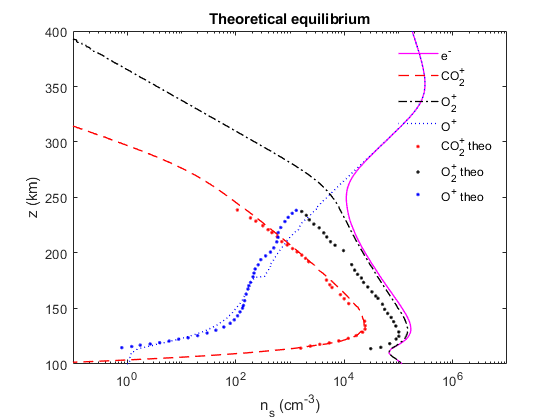

data = fulldata;
Z = line1(:,1);

for i=length(badi):-1:1
    data(badi(i),:) = [];
    Z(badi(i)) = [];
end
figure;
if s1+s2+s3 ~= 0
    semilogx(data(:,4),Z,'DisplayName','e^-','LineWidth',1,'Color','m','LineStyle','-');
    hold on;
end

if s1
    semilogx(data(:,1),Z,'DisplayName','CO_2^+','LineWidth',1,'Color','r','LineStyle','--');
end
if s2
    semilogx(data(:,2),Z,'DisplayName','O_2^+','LineWidth',1,'Color','k','LineStyle','-.');
end
if s3
    semilogx(data(:,3),Z,'DisplayName','O^+','LineWidth',1,'Color','b','LineStyle',':');
end


Plot_theoretical(1,1,1);
Plot_ion_profiles(x0,line1(:,1),0,0,0);


legend('show','Location','northeast');
legend boxoff;
title('Theoretical equilibrium');
xlabel("n_s (cm^-^3)");
ylabel("z (km)");
xlim([1e-1,1e7]);
ylim([100 400]);


%disp("Points maximum    = "+n);
%disp("Points attempted  = "+(numsolved+numskipped));
%disp("Points successful = "+numsolved);
%disp("Points failed     = "+numskipped);

%Plot_neutral_profiles(line1);

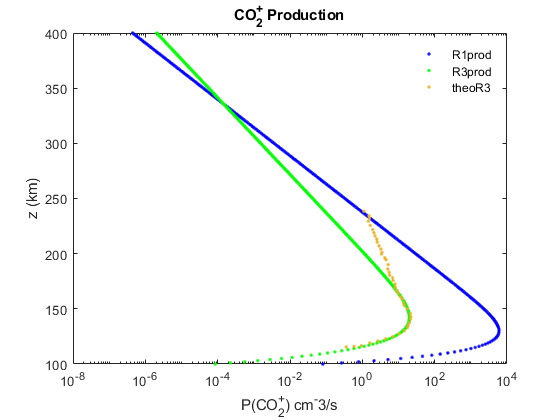

return;
Y = line1(:,1);

CO2_peak = 130;
scale_height = 11.1;
z = (Y-CO2_peak)/scale_height;
q_max = 6e3;
R1prod = q_max*exp(1-z-exp(-z));

O_peak = 142;
scale_height = 15.1;
z = (Y-O_peak)/scale_height;
q_max = 2e1;
R3prod = q_max*exp(1-z-exp(-z));

theoR3 = [0.35954004853365584, 115.48603324518137,0.591697000579214, 115.90991970318854,0.9406236163838522, 116.5721119160225,1.6110806597014142, 119.12650764449504,2.658746169740552, 120.78664208621126,4.390706111605269, 122.75176793744993,7.091606471602114, 124.88903070379556,10.472009766917273, 127.37092700783154,14.540782408045882, 130.12370731758955,17.77829496688749, 133.01092069717856,18.59956950876091, 134.90665284037465,19.892698080716404, 137.3250239034117,21.585661312483573, 140.81430623264956,21.938878386227117, 142.91231288964474,21.217031865631867, 145.8937162346395,17.313296722578652, 149.93814657777142,14.45713699868401, 153.04013381869106,13.776884894728306, 155.5368510277208,12.51824104315846, 158.99668943768432,11.37607530779562, 160.83990623610737,9.7526180556478, 164.05982808590943,9.125147663523752, 166.64787327812394,8.124431303032262, 169.55189756410311,8.012983823884094, 172.50237843655214,7.101984482975169, 175.7845726495129,6.826968773509865, 178.32252543266213,5.689511546408715, 180.5486870777924,5.506121912153447, 183.20770743844284,5.043787198479748, 186.08286470688796,5.186459067669307, 190.11127616071877,4.505705284190806, 194.54191867860214,4.195595612899612, 196.33228524027595,3.4191464837294943, 199.74059238781373,3.495121573784429, 201.166080514643,3.2470666151273715, 204.14806153903032,2.8978694332685206, 207.1306202428102,2.588538507421607, 210.51062236867037,2.495853782685501, 213.26393850631712,2.2432342665611187, 216.06131853231938,2.1026785560419397, 218.9836922947179,1.9397242267326444, 221.7669335045873,1.6539055185861087, 225.62040456043218,1.4710470752835585, 229.4315272144136,1.5718877983828796, 232.11458471756356,1.52188477226462, 234.48897633458412,1.1046261140446532, 238.43826889056288];
j = 1;
while j <= length(theoR3)-1
    theoR3x(ceil(j/2)) = theoR3(j);
    theoR3y(ceil(j/2)) = theoR3(j+1);
    j = j+2;
end


figure;
semilogx(R1prod ,Y,'.','DisplayName','R1prod','Color','b');
hold on;
semilogx(R3prod ,Y,'.','DisplayName','R3prod','Color','g');
semilogx(theoR3x,theoR3y,'.','DisplayName','theoR3');
%semilogx(R6prod,Y,'.','DisplayName','R6 loss','Color','r');
%semilogx(R8prod,Y,'.','DisplayName','R8 loss');
%semilogx(exper9,Y,'.','DisplayName','R9 loss');
%semilogx(R6prod+R8prod+R9prod,Y,'.','DisplayName','Total loss','Color','c');
%net = R1prod-(R6prod+R8prod+R9prod);
%semilogx(abs(net),Y,'.','DisplayName','Net','Color','k');

legend('show','Location','northeast');
legend boxoff;
title("CO_2^+ Production");
xlabel("P(CO_2^+) cm^-3/s");
ylabel("z (km)");

function F = SOEall(x)
    global v1 k2 v3 k4 k5 k6 k7 k8 k9 k10 CO2 O CO2p_0 O2p_0 Op_0 alt
    global R1 R2 R3 R4 R5 R6 R7 R8 R9 R10 s1 s2 s3 temp
    
    CO2p = x(1);
    O2p  = x(2);
    Op   = x(3);
    ne   = x(4);
    
    CO2p = CO2p + (1-s1)*(-CO2p + CO2p_0);  % equals CO2p_0 if s1 is 0, equals CO2p if s1 is 1
    O2p  = O2p +  (1-s2)*(-O2p + O2p_0);
    Op   = Op +   (1-s3)*(-Op + Op_0);
    
    R(1)  = R1 *(v1*CO2);
    R(2)  = R2 *(k2*CO2*ne);
    R(3)  = R3 *(v3*O);
    R(4)  = R4 *(k4*O*ne);
    R(5)  = R5 *(k5*O2p*ne);
    R(6)  = R6 *(k6*CO2p*ne);
    R(7)  = R7 *(k7*Op*ne);
    R(8)  = R8 *(k8*CO2p*O);
    R(9)  = R9 *(k9*CO2p*O);
    R(10) = R10*(k10*Op*CO2);
    
    
    %%%%%%%%%%%%%%%%%%%%% test Tascione Eq 7.16
    CO2_peak = 130;
    scale_height = 11.1;
    z = (alt-CO2_peak)/scale_height;
    q_max = 6e3;
    
    R(1) = q_max*exp(1-z-exp(-z));
    
    %{
    O_peak = 130;
    scale_height = 11.1;
    z = (alt-O_peak)/scale_height;
    q_max = 6e3;
    
    R(3) = q_max*exp(1-z-exp(-z));
    %}
    %%%%%%%%%%%%%%%%%%%%%%%
    
    CO2p_S = R(1) + R(2);
    CO2p_L = R(6) + R(8) + R(9);

    O2p_S  = R(8) + R(10);
    O2p_L  = R(5);

    Op_S   = R(3) + R(4) + R(9);
    Op_L   = R(7) + R(10);
    
    F = [s1*(CO2p_S - CO2p_L),...
         s2*(O2p_S  - O2p_L),...
         s3*(Op_S   - Op_L),...
         ne-(CO2p + O2p + Op)];
end


function Plot_theoretical(x,y,z)
    tempCO2 = [107.28443014544911, 238.81087784813934,186.81809528372952, 231.66782071435557,234.7542544916016, 228.73721448609507,314.6875438309644, 224.59740261321213,395.03062258963615, 221.05560394575534,464.5663141383297, 218.36082281080465,583.1088976231371, 214.75111387232602,706.8980779994838, 210.28593692918963,888.1486408313958, 207.26478367290005,1115.366197275364, 203.97198933252324,1355.6298531130644, 201.0461118658813,1647.6492681422417, 198.12023439923934,1936.9460712938242, 195.19908569421594,2202.083207554452, 192.19211872278197,4713.658420891596, 175.60064559651647,5408.092713513752, 171.41499100683157,5952.282040476774, 168.95603496519067,8496.361932707108, 162.52045311133625,9975.335409790083, 158.82965466806564,12094.845277034583, 154.45502475295834,23717.072856163344, 138.60053788190828,24352.137742153875, 134.46686464216347,24228.71247608603, 131.42448450038623,21823.663513818727, 128.6950958359606,16631.980222543043, 125.6769637329273,11868.059507423008, 123.16629780729107,7924.805887082224, 120.82354670394281,5296.532173844187, 119.02407776876905,3542.6070491965934, 117.67734397374073,2368.7705537823995, 116.14951612265423,1582.9248605572204, 114.25950015945139];
    j = 1;
    while j <= length(tempCO2)-1
        tempCO2x(ceil(j/2)) = tempCO2(j);
        tempCO2y(ceil(j/2)) = tempCO2(j+1);
        j = j+2;
    end
    tempO2 = [30716.31948711234, 113.83864037540133,47152.29831133881, 115.02766121348537,68868.39878425805, 118.34304852603967,90537.83835885575, 122.50056406510558,101597.60708683495, 124.98993596851514,101130.9232323651, 128.88503442763863,89302.21869106576, 134.22811472222295,81336.75599658009, 138.15393261793503,73250.23190306373, 141.97267033388505,63079.59146276196, 145.59398225226101,55546.61432835882, 149.26948811397637,50646.90116378556, 153.84422637723023,41837.88091825807, 159.1696000866429,37986.97917918481, 161.22109450215294,32362.254713340222, 165.0477134874672,27139.47268453116, 169.41997902176522,22749.762040949743, 173.53418552618035,20721.028505316535, 177.4735854760968,17636.859602341927, 180.75692229323653,15534.459851840646, 184.57881251693226,13708.773140758605, 189.54159529379444,9703.790463509347, 202.17059386483822,6779.688133550657, 206.9763292141691,5580.6283729526585, 210.1738477648983,4758.261881010145, 214.49847540437253,4190.103243889844, 218.18454508602463,3456.6103834335577, 222.69499554317554,2752.6528624501793, 226.0330633975669,2268.559894104719, 229.9549581725288,1998.7409193875378, 233.95794245228268,1645.9889733005732, 237.42710208709912];
    j = 1;
    while j <= length(tempO2)-1
        tempO2x(ceil(j/2)) = tempO2(j);
        tempO2y(ceil(j/2)) = tempO2(j+1);
        j = j+2;
    end
    tempO = [0.7937273274502612, 114.7491021262895,1.2100019186430861, 115.76702936344202,1.737870386168309, 117.01983594158062,2.64942610966869, 118.06492728714184,3.95994441352583, 119.23056702611197,5.921386363699842, 120.66784784916939,8.85771906416737, 122.33149624229952,13.24312670265674, 123.67823003732786,19.817699092943634, 125.56824600053068,29.678661595817765, 127.91099710387894,43.001413018341694, 130.4214616192981,60.30030820122635, 133.30789771125504,79.17156352437125, 136.69274527780613,94.01334775449823, 139.79297393671683,108.07692789910513, 143.4412135254206,120.14537647205104, 146.95836133369926,133.53115884527594, 150.33968859993433,145.9623927163447, 157.0744084109912,138.62657488932382, 152.8068937035098,155.82177194156677, 162.95208396351745,167.84926762636397, 167.5605248697637,174.40449980667086, 170.54384803310495,187.35565564568742, 173.52244243482767,208.79714372426574, 178.5336162055862,228.3734529267478, 185.63052412875942,217.09925658178955, 181.92440099505836,259.67559788477456, 189.37088699936515,289.21857173008755, 194.01987265800736,355.26075127163136, 197.43228715340135,436.38346126634383, 200.8447016487953,501.7764469216845, 204.6287617795427,570.8816677876953, 210.04455991946105,606.6152466081313, 218.45881325989996,602.2278199242932, 214.11255591450387,675.4503379316304, 222.9493416194913,805.1412358876071, 228.3358827361364,925.7933548660269, 232.11994286688378,1100.3438459377821, 235.76345369396898,1305.7293536175819, 238.45622072674882];
    j = 1;
    while j <= length(tempO)-1
        tempOx(ceil(j/2)) = tempO(j);
        tempOy(ceil(j/2)) = tempO(j+1);
        j = j+2;
    end
    if x
        semilogx(tempCO2x,tempCO2y,'.','DisplayName','CO_2^+ theo','Color','r');
    end
    if y
        semilogx(tempO2x,tempO2y,'.','DisplayName','O_2^+ theo','Color','k');
    end
    if z
        semilogx(tempOx,tempOy,'.','DisplayName','O^+ theo','Color','b');
    end
end


function Plot_ion_profiles(x0,Z,x,y,z)
    if x
        semilogx(x0(:,1),Z,'x','DisplayName','CO_2^+ init','Color','r');
    end
    if y
        semilogx(x0(:,2),Z,'x','DisplayName','O_2^+ init','Color','k');
    end
    if z
        semilogx(x0(:,3),Z,'x','DisplayName','O^+ init','Color','b');
    end
end


function Plot_neutral_profiles(data)
    figure;
    Z = data(:,1);    
    x1 = data(:,2);
    x2 = data(:,3);
    semilogx(x1,Z,'.','DisplayName','O','Color','r');
    hold on;
    semilogx(x2,Z,'.','DisplayName','CO_2','Color','k');
    hold off;
    
    legend('show','Location','northeast');
    legend boxoff;
    title('Neutral Density Profiles');
    xlabel("n_s (cm^-^3)");
    ylabel("z (km)");
    %xlim([1e-1,1e7]);
    ylim([100 400]);
end